# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 임하늘**

**학번**** : 201911682**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :https://github.com/Haneul00/Digital-Design.git**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

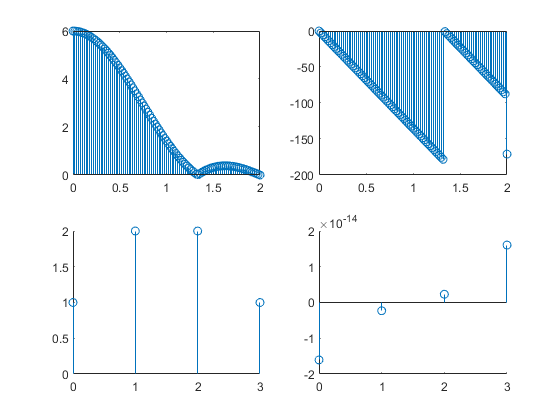

%-----------DFT-------------
xn = [1,2,2,1];
N = 4;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;

Xk = xn*WNnk;

dft_magX = abs(Xk);
dft_phaX = angle(Xk)*180/pi;
subplot(2,2,1); 
stem(k,dft_magX)
subplot(2,2,2); 
stem(k,dft_phaX)
%-----------IDFT-------------
N = 4;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^(-nk);
xn = (Xk * WNnk)/N;
Xk = [6, -1-j, 0, -1+j];

idft_magX = abs(xn);
idft_phaX = angle(xn)*180/pi;
subplot(2,2,3); hold on;
stem(n,idft_magX)
subplot(2,2,4); hold on;
stem(n,idft_phaX)
%----------dtft

k1 = [0:1:100];
w = (pi/100)*k1;
X = xn*(exp(-j*pi/100)).^(n'*k1);
mag_X = abs(X);
pha_X = angle(X)*180/pi;
dw = (2*pi)/N;
subplot(2,2,1);

stem(w/dw, mag_X);
hold on;
subplot(2,2,2);
stem(w/dw,pha_X);
hold on

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

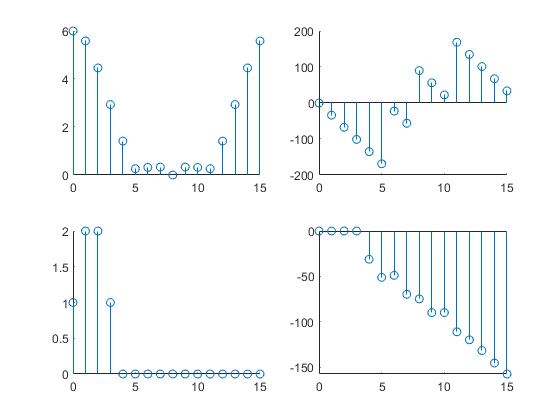

%-----------DFT-------------
xn = [1,2,2,1, zeros(1,12)];
N = 16;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;

Xk = xn*WNnk;

dft_magX = abs(Xk);
dft_phaX = angle(Xk)*180/pi;
figure
subplot(2,2,1); hold on;
stem(k,dft_magX)
subplot(2,2,2); hold on;
stem(k,dft_phaX)

%-----------IDFT-------------
N = 16;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^(-nk);
xn = (Xk*WNnk)/N;

idft_magX = abs(xn);
idft_phaX = angle(xn)*180/pi;
subplot(2,2,3); hold on;
stem(n,idft_magX)
subplot(2,2,4); hold on;
stem(n,idft_phaX)

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$


$$\tilde{X} \left(0\right)=5$$



$$\tilde{X} \left(1\right)=5+0\ldotp 0000i$$



$$\tilde{X} \left(2\right)=1-\;0\ldotp 0000i$$



$$\tilde{X} \left(3\right)=5+\;0\ldotp 0000i$$


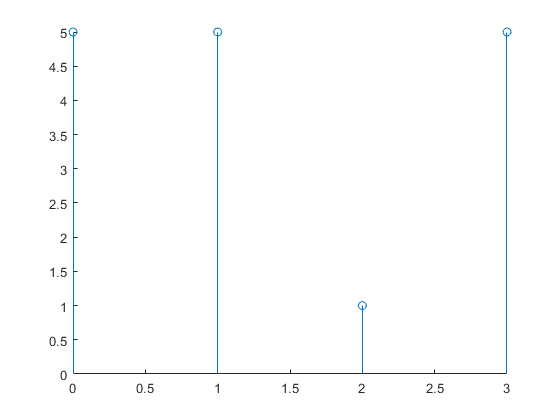

xn = [4,1,-1,1];
N = 4;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
dfs_Xk1 = xn*WNnk;
figure
subplot(1,1,1); hold on;
stem(k,dfs_Xk)

2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


$$\tilde{X} \left(0\right)=-1$$



$$\tilde{X} \left(1\right)=2\ldotp 618+0\ldotp 0000i$$



$$\tilde{X} \left(2\right)=0\ldotp 382-\;0\ldotp 0000i$$



$$\tilde{X} \left(3\right)=0\ldotp 382$$



$$\tilde{X} \left(4\right)=2\ldotp 618+\;0\ldotp 0000i$$


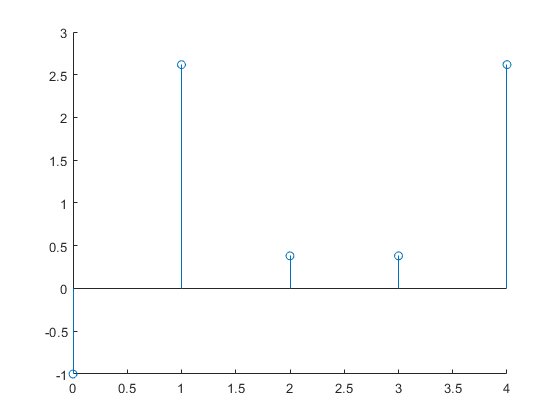

xn = [1,0,-1,-1,0];
N = 5;
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
dfs_Xk2 = xn*WNnk;
figure
subplot(1,1,1); hold on;
stem(k,dfs_Xk2)

3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

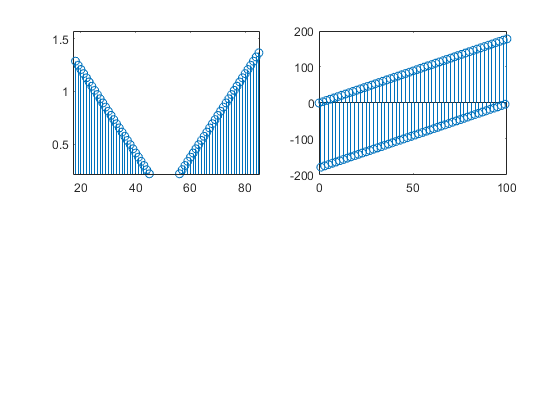

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
k = 0:N-1;
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
Xk = xn*WNnk;

mag_Xk = abs(Xk);
pha_Xk = angle(Xk)*180/pi;
zei = find(mag_Xk < 0.00001); 
pha_Xk(zei) = zeros(1,length(zei));

figure
subplot(2,2,1);
stem(k,mag_Xk);
subplot(2,2,2);
stem(k,pha_Xk);

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

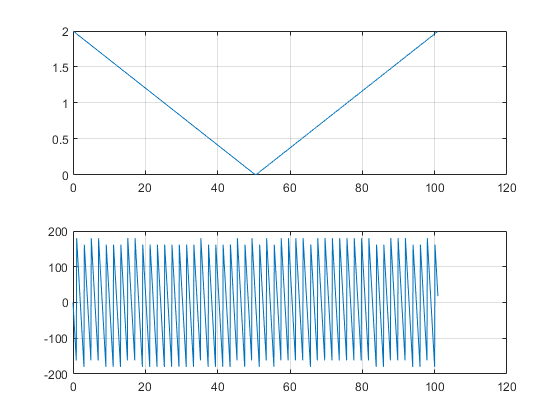

[X,w] = freqz(xn,1,1000,'whole');
mag_X = abs(X); pha_X = angle(X)*180/pi;
Dw = (2*pi)/N;
subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

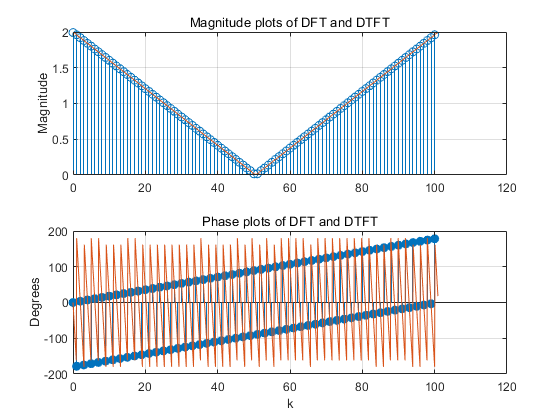

subplot(2,1,1);
stem(k,mag_Xk); hold on
ylabel('Magnitude');
title('Magnitude plots of DFT and DTFT'); hold on

subplot(2,1,2); 
H_s2 = stem(k,pha_Xk,'filled'); 
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT and DTFT'); hold on

subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

 만약 주파수 영역에서의 샘플개수가 신호의 크기보다 크거나 같게해줄 경우, DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있다.


$$X\left(e^{\textrm{jw}} \right)=\sum_{k=0}^{100} X\left(k\right)e^{-j\left(50\right)\omega } \frac{\sin \left(50\ldotp 5\omega \right)}{101\sin \left(\frac{\omega }{2}\right)}$$
